# Sample 13-4

## 辞書学習

畳込み辞書学習

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Dictionary learning

Convolutional dictionary learning

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all

nsoltDic = "nsoltdictionary_20230620211447804"; % Set "" if you train new dictionary.

isCodegen = false; % コード生成
msip.saivdr_setup(isCodegen)

SaivDr-4.2.2.2 exits.
Skip code generation



import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### パラメータ設定

- ブロックサイズ 

- 冗長度

- スパース度

% Block size
szBlk = [ 8 8 ];

% Redundancy ratio 
redundancyRatio = 7/3; 

% Sparsity ratio 
sparsityRatio = 3/64;

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


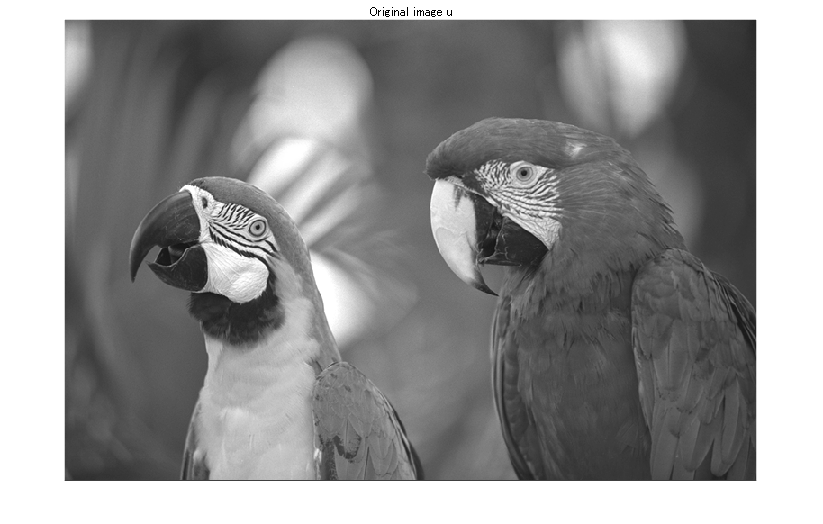

file_uorg = './data/kodim23.png';
u = rgb2gray(im2double(imread(file_uorg)));
szOrg = size(u);
figure
imshow(u);
title('Original image u')

meansubtract = @(x) x-mean(x,"all");
y = meansubtract(u);

% # of patches
nPatches = prod(szOrg./szBlk); 

## 2変量ラティス構造冗長フィルタバンク

(Bivariate lattice-structure oversampled filter banks) 

例として，（偶対称チャネルと奇対称チャネルが等しい）偶数チャネル、偶数のポリフェーズ次数をもつタイプI非分離冗長重複変換(NSOLT)

(As an example, let us adopt a non-separable oversampled lapped transform (NSOLT) of  type-I with the number of channels (the numbers of even and odd symmetric channels are identical to each other) and polyphase order (even):)

        
$$\mathbf{E}(z_\mathrm{v},z_\mathbf{h})
=
\left(\prod_{k_\mathrm{h}=1}^{N_\mathrm{h}/2}
{\mathbf{V}_{2k_\mathrm{h}}^{\{\mathrm{h}\}}}\bar{\mathbf{Q}}(z_\mathrm{h}){\mathbf{V}_{2k_\mathrm{h}-1}^{\{\mathrm{h}\}}}{\mathbf{Q}}(z_\mathrm{h})\right)
%
\left(\prod_{k_{\mathrm{v}}=1}^{N_\mathrm{v}/2}{\mathbf{V}_{2k_\mathrm{v}}^{\{\mathrm{v}\}}}\bar{\mathbf{Q}}(z_\mathrm{v}){\mathbf{V}_{2k_\mathrm{v}-1}^{\{\mathrm{v}\}}}{\mathbf{Q}}(z_\mathrm{v})\right)
%
\mathbf{V}_0\mathbf{E}_0,$$


        
$$\mathbf{R}(z_\mathrm{v},z_\mathbf{h})
=\mathbf{E}^T(z_\mathrm{v}^{-1},z_\mathrm{h}^{-1}),$$


を採用する．ただし，(where)

- $\mathbf{E}(z_\mathrm{v},z_\mathrm{h})$:  Type-I polyphase matrix of the analysis filter bank

- $\mathbf{R}(z_\mathrm{v},z_\mathrm{h})$: Type-II polyphase matrix in the synthesis filter bank

- $z_d\in\mathbb{C}, d\in\{\mathrm{v},\mathrm{h}\}$: The parameter of Z-transformation direction

- $N_d\in \mathbb{N}, d\in\{\mathrm{v},\mathrm{h}\}$: Polyphase order in direction $d$ (number of overlapping blocks)

- $\mathbf{V}_0=\left(\begin{array}{cc}\mathbf{W}_{0} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_0\end{array}\right)
%
\left(\begin{array}{c}\mathbf{I}_{M/2} \\ 
\mathbf{O} \\
\mathbf{I}_{M/2} \\
\mathbf{O}
\end{array}\right)\in\mathbb{R}^{P\times M}$,$\mathbf{V}_n^{\{d\}}=\left(\begin{array}{cc}\mathbf{I}_{P/2} & \mathbf{O} \\\mathbf{O} & \mathbf{U}_n^{\{d\}}\end{array}\right)\in\mathbb{R}^{P\times P}, d\in\{\mathrm{v},\mathrm{h}\}$, where$\mathbf{W}_0, \mathbf{U}_0,\mathbf{U}_n^{\{d\}}\in\mathbb{R}^{P/2\times P/2}$are orthonromal matrices.

- $\mathbf{Q}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  z^{-1}\mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\bar{\mathbf{Q}}(z)=\mathbf{B}_{P}\left(\begin{array}{cc} z\mathbf{I}_{P/2} &  \mathbf{O} \\ \mathbf{O} &  \mathbf{I}_{P/2}\end{array}\right)\mathbf{B}_{P}$, $\mathbf{B}_{P}=\frac{1}{\sqrt{2}}\left(\begin{array}{cc} \mathbf{I}_{P/2} &  \mathbf{I}_{P/2} \\ \mathbf{I}_{P/2} &  -\mathbf{I}_{P/2}\end{array}\right)$

です。

【References】 

- [Overview of Filter Banks - MATLAB & Simulink - MathWorks 日本](https://jp.mathworks.com/help/dsp/ug/overview-of-filter-banks.html)

- MATLAB SaivDr Package: [https://github.com/msiplab/SaivDr](https://github.com/msiplab/SaivDr)

- S. Muramatsu, K. Furuya and N. Yuki, "Multidimensional Nonseparable Oversampled Lapped Transforms: Theory and Design," in IEEE Transactions on Signal Processing, vol. 65, no. 5, pp. 1251-1264, 1 March1, 2017, doi: 10.1109/TSP.2016.2633240.

- S. Muramatsu, T. Kobayashi, M. Hiki and H. Kikuchi, "Boundary Operation of 2-D Nonseparable Linear-Phase Paraunitary Filter Banks," in IEEE Transactions on Image Processing, vol. 21, no. 4, pp. 2314-2318, April 2012, doi: 10.1109/TIP.2011.2181527.

- S. Muramatsu, M. Ishii and Z. Chen, "Efficient parameter optimization for example-based design of nonseparable oversampled lapped transform," 2016 IEEE International Conference on Image Processing (ICIP), Phoenix, AZ, 2016, pp. 3618-3622, doi: 10.1109/ICIP.2016.7533034.

- Furuya, K., Hara, S., Seino, K., & Muramatsu, S. (2016). Boundary operation of 2D non-separable oversampled lapped transforms. *APSIPA Transactions on Signal and Information Processing, 5*, E9. doi:10.1017/ATSIP.2016.3.

## 2次元画像の階層的分析

(Hierachical decomposition for 2-D Grayscale image)

$R_M^P(\tau)$ をツリーレベル $\tau$の階層構造フィルタバンクの冗長度とすると、

 (Let $R_M^P(\tau)$ be the redundancy of $\tau$-level tree-structured filter bank, then we have the relation )

    
$$R_M^P(\tau)=\left\{\begin{array}{ll} (P-1)\tau + 1, & M=1, \\ \frac{P-1}{M-1}-\frac{P-M}{(M-1)M^\tau}, & M\geq 2.\end{array}\right.$$


となる．

#### 構成パラメータ設定

%%{
% Decimation factor (Strides)
decFactor = [2 2]; % [μv μh] 

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [4 4]; % [Ps Pa] (Ps=Pa)

% Number of tree levels
nLevels = 4; 

% Polyphase Order
ppOrder = [4 4]; 
%%}

%{
% Decimation factor (Strides)
decFactor =  [4 4]; % [μv μh] 

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [13 13]; % [Ps Pa] (Ps=Pa)

% Number of tree levels
nLevels = 2; 

% Polyphase Order
ppOrder = [2 2];
%}

%{
% Decimation factor (Strides)
decFactor =  [8 8]; % [μv μh] 

% Number of channels ( sum(nChannels) >= prod(decFactors) )
nChannels = [53 53]; % [Ps Pa] (Ps=Pa)

% Number of tree levels
nLevels = 1; 

% Polyphase Order
ppOrder = [2 2];
%}

% Redundancy
P = sum(nChannels);
M = prod(decFactor);
redundancyNsolt = ...
    (prod(decFactor)==1)*((P-1)*nLevels+1) + ...
    (prod(decFactor)>1)*((P-1)/(M-1)-(P-M)/((M-1)*M^nLevels))

redundancyNsolt = 2.3281

assert(redundancyNsolt<redundancyRatio)



$$L_\mathrm{v}\times L_\mathrm{h}=\left(\mu_\mathrm{v}^{\tau}+{\nu}_\mathrm{v}\frac{\mu_\mathrm{v}(\mu_\mathrm{v}^{\tau}-1)}{\mu_\mathrm{v}-1}\right) \times\left(\mu_\mathrm{h}^{\tau}+\nu_\mathrm{h}\frac{\mu_\mathrm{h}(\mu_\mathrm{h}^{\tau}-1)}{\mu_\mathrm{h}-1}\right)$$
 

% Filter size [ Ly Lx ]
maxDecFactor = decFactor.^nLevels;
szFilters = maxDecFactor + ppOrder.*decFactor.*(maxDecFactor-1)./(decFactor-1)

szFilters =    136   136



% Patch size for training
szPatchTrn = maxDecFactor.*ceil(szFilters./maxDecFactor) % > [ Ly Lx ]

szPatchTrn =    144   144


%szPatchTrn = 2.^nextpow2(szFilters) % > [ Ly Lx ]
assert(all(szPatchTrn>szFilters))

% Number of patchs per image
nSubImgs = floor(nPatches*prod(szBlk./szPatchTrn))

nSubImgs = 18

assert(nSubImgs > 0)

% No DC-leakage
noDcLeakage = true

noDcLeakage = logical
   1


#### 辞書の設定

maxIters = 54

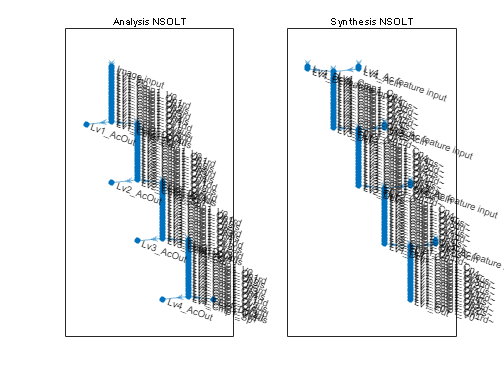

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

if exist("./data/"+nsoltDic+".mat","file")
    S = load("./data/"+nsoltDic);
    analysisnet = S.analysisnet;
    synthesisnet = S.synthesisnet;
    nLevels_ = extractnumlevels(analysisnet);
    decFactor_ = extractdecfactor(analysisnet);
    nChannels_ = extractnumchannels(analysisnet);

    assert(nLevels==nLevels_)
    assert(all(decFactor==decFactor_))
    assert(all(nChannels==nChannels_))
else
    % Number of iterations
    nItersNsolt = 10;

    % Standard deviation of initial angles
    stdInitAng = 1e-1; %pi/6;

    % Mini batch size
    miniBatchSize = 10;

    % Number of Epochs (1 Epoch = nSubImgs/miniBachSize iterlations)
    maxEpochs = 30;

    % Number of iterations
    maxIters = nSubImgs/miniBatchSize * maxEpochs

    % Training options
    opts = trainingOptions('sgdm', ... % Stochastic gradient descent w/ momentum
        ...'Momentum', 0.9000,...
        'InitialLearnRate',1e-02,...
        ...'LearnRateScheduleSettings','none',...
        'L2Regularization',0.0, ... 1.0e-04,... 
        ...'GradientThresholdMethod','l2norm',...
        ...'GradientThreshold',Inf,...
        'MaxEpochs',maxEpochs,...30,...
        'MiniBatchSize',miniBatchSize,...128,...
        'Verbose',1,...
        ...'VerboseFrequency',50,...
        ...'ValidationData',[],...
        ...'ValidationFrequency',50,...
        ...'ValidationPatience',Inf,...
        ...'Shuffle','once',...
        ...'CheckpointPath','',...
        ...'ExecutionEnvironment','auto',...
        ...'WorkerLoad',[],...
        ...'OutputFcn',[],...
        'Plots','none',...'training-progress',...
        ...'SequenceLength','longest',...
        ...'SequencePaddingValue',0,...
        ...'SequencePaddingDirection','right',...
        ...'DispatchInBackground',0,...
        'ResetInputNormalization',0);...1

## 層構造の構築

(Construction of layers)

  import saivdr.dcnn.*
    analysislgraph = fcn_creatensoltlgraph2d([],...
        'InputSize',szPatchTrn,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...
        'NumberOfLevels',nLevels,...

    "MSE: 3.9483e-10"



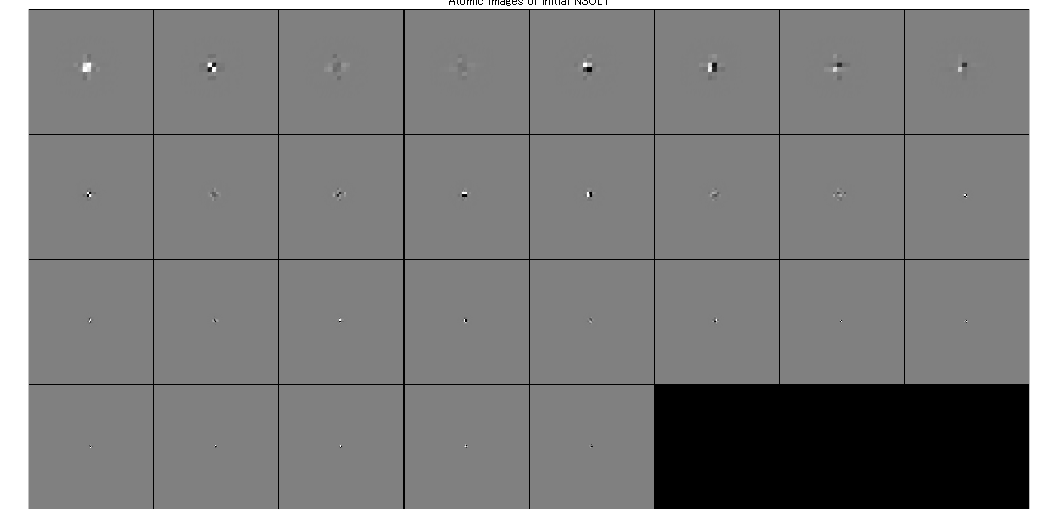

        'NumberOfVanishingMoments',noDcLeakage,...
        'Mode','Analyzer');
    synthesislgraph = fcn_creatensoltlgraph2d([],...
        'InputSize',szPatchTrn,...
        'NumberOfChannels',nChannels,...
        'DecimationFactor',decFactor,...
        'PolyPhaseOrder',ppOrder,...

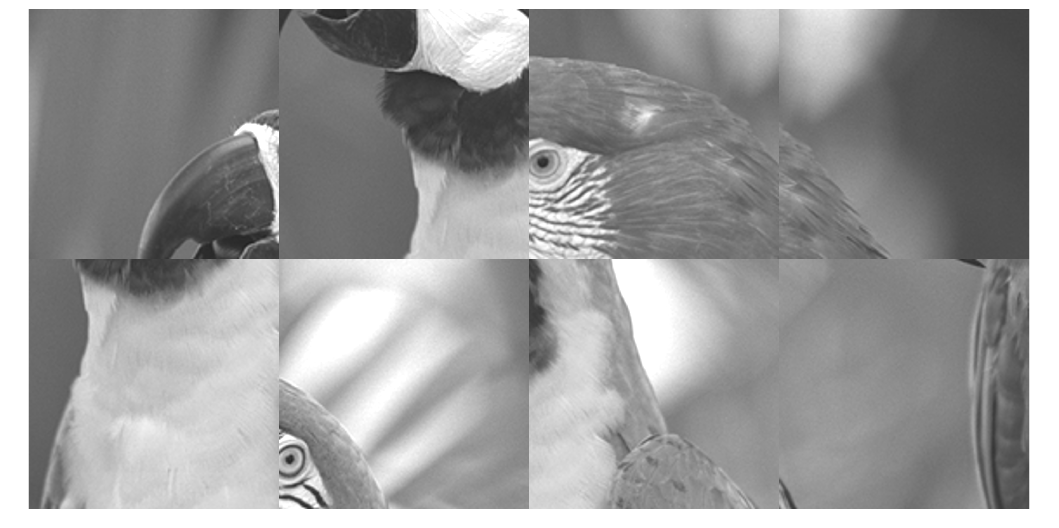

        'NumberOfLevels',nLevels,...
        'NumberOfVanishingMoments',noDcLeakage,...
        'Mode','Synthesizer');

    figure
    subplot(1,2,1)
    plot(analysislgraph)
    title('Analysis NSOLT')
    subplot(1,2,2)
    plot(synthesislgraph)
    title('Synthesis NSOLT')

    % Construction of deep learning network.

    synthesisnet = dlnetwork(synthesislgraph);

    % Initialize
    nLearnables = height(synthesisnet.Learnables);
    for iLearnable = 1:nLearnables
        if synthesisnet.Learnables.Parameter(iLearnable)=="Angles"
            layerName = synthesisnet.Learnables.Layer(iLearnable);
            synthesisnet.Learnables.Value(iLearnable) = ...
                cellfun(@(x) x+stdInitAng*randn(size(x)), ...
                synthesisnet.Learnables.Value(iLearnable),'UniformOutput',false);
        end
    end

    % Copy the synthesizer's parameters to the analyzer
    synthesislgraph = layerGraph(synthesisnet);
    analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);
    analysisnet = dlnetwork(analysislgraph);

### 随伴関係（完全再構成）の確認

(Confirmation of the adjoint relation (perfect reconstruction))

NSOLTはパーセバルタイト性を満たすことに注意．(Note that NSOLT satisfy the Parseval tight property.)

    nOutputs = nLevels+1;
    x = rand(szPatchTrn,'single');
    s = cell(1,nOutputs);
    dlx = dlarray(x,'SSCB'); % Deep learning array (SSCB: Spatial,Spatial,Channel,Batch)
    [s{1:nOutputs}] = analysisnet.predict(dlx);
    dly = synthesisnet.predict(s{:});
    display("MSE: " + num2str(mse(dlx,dly)))

### 要素画像の初期状態

(Initial state of the atomic images)

    import saivdr.dcnn.*
    figure
    atomicimshow(synthesisnet,[],2^(nLevels-1))
    title('Atomic images of initial NSOLT')

単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１５　｜　　　　　　　　　４．２２　｜　　　　　　　８．９　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５５　｜　　　　　　　　　３．６３　｜　　　　　　　６．６　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 3.3028e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１４　｜　　　　　　　　　４．０２　｜　　　　　　　８．１　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５６　｜　　　　　　　　　２．５１　｜　　　　　　　３．１　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 3.2281e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１４　｜　　　　　　　　　３．６６　｜　　　　　　　６．７　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５７　｜　　　　　　　　　２．７１　｜　　　　　　　３．７　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.7323e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１５　｜　　　　　　　　　３．３２　｜　　　　　　　５．５　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５５　｜　　　　　　　　　３．２９　｜　　　　　　　５．４　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 3.6447e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１５　｜　　　　　　　　　２．９７　｜　　　　　　　４．４　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５７　｜　　　　　　　　　４．８３　｜　　　　　　１１．７　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.882e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１５　｜　　　　　　　　　４．４２　｜　　　　　　　９．８　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５６　｜　　　　　　　　　４．０７　｜　　　　　　　８．３　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 3.4416e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１４　｜　　　　　　　　　２．７０　｜　　　　　　　３．６　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５０　｜　　　　　　　　　３．６７　｜　　　　　　　６．７　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.7222e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１４　｜　　　　　　　　　４．０３　｜　　　　　　　８．１　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：４９　｜　　　　　　　　　４．３６　｜　　　　　　　９．５　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.5182e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１５　｜　　　　　　　　　２．０５　｜　　　　　　　２．１　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５３　｜　　　　　　　　　３．１７　｜　　　　　　　５．０　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 2.4799e-14"



単一の GPU で学習中。
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　エポック　　｜　　反復　　｜　　　　　経過時間　　　　　｜　　ミニバッチ　ＲＭＳＥ　　｜　　ミニバッチ損失　　｜　　基本学習率　　｜
｜　　　　　　　　｜　　　　　　｜　　（ｈｈ：ｍｍ：ｓｓ）　　｜　　　　　　　　　　　　　　｜　　　　　　　　　　　｜　　　　　　　　　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
｜　　　　　　１　｜　　　　１　｜　　　　　００：００：１４　｜　　　　　　　　　３．４１　｜　　　　　　　５．８　｜　　０．０１００　｜
｜　　　　　３０　｜　　　３０　｜　　　　　００：０３：５０　｜　　　　　　　　　４．１９　｜　　　　　　　８．８　｜　　０．０１００　｜
｜＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝＝｜
学習終了: 最大数のエポックが完了しました。


Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    "MSE: 3.0318e-14"



### 訓練画像の準備

(Preparation of traning image)

画像データストアからランダムにパッチを抽出

(Randomly extracting patches from the image data store)

    imds = imageDatastore(file_uorg,"ReadFcn",@(x) meansubtract(rgb2gray(im2single(imread(x)))));
    patchds = randomPatchExtractionDatastore(imds,imds,szPatchTrn,'PatchesPerImage',nSubImgs);
    figure

Copy angles from Lv1_Cmp1_V0~ to Lv1_Cmp1_V0
Copy angles from Lv1_Cmp1_Vh1~ to Lv1_Cmp1_Vh1
Copy angles from Lv1_Cmp1_Vh2~ to Lv1_Cmp1_Vh2
Copy angles from Lv1_Cmp1_Vh3~ to Lv1_Cmp1_Vh3
Copy angles from Lv1_Cmp1_Vh4~ to Lv1_Cmp1_Vh4
Copy angles from Lv1_Cmp1_Vv1~ to Lv1_Cmp1_Vv1
Copy angles from Lv1_Cmp1_Vv2~ to Lv1_Cmp1_Vv2
Copy angles from Lv1_Cmp1_Vv3~ to Lv1_Cmp1_Vv3
Copy angles from Lv1_Cmp1_Vv4~ to Lv1_Cmp1_Vv4
Copy angles from Lv2_Cmp1_V0~ to Lv2_Cmp1_V0
Copy angles from Lv2_Cmp1_Vh1~ to Lv2_Cmp1_Vh1
Copy angles from Lv2_Cmp1_Vh2~ to Lv2_Cmp1_Vh2
Copy angles from Lv2_Cmp1_Vh3~ to Lv2_Cmp1_Vh3
Copy angles from Lv2_Cmp1_Vh4~ to Lv2_Cmp1_Vh4
Copy angles from Lv2_Cmp1_Vv1~ to Lv2_Cmp1_Vv1
Copy angles from Lv2_Cmp1_Vv2~ to Lv2_Cmp1_Vv2
Copy angles from Lv2_Cmp1_Vv3~ to Lv2_Cmp1_Vv3
Copy angles from Lv2_Cmp1_Vv4~ to Lv2_Cmp1_Vv4
Copy angles from Lv3_Cmp1_V0~ to Lv3_Cmp1_V0
Copy angles from Lv3_Cmp1_Vh1~ to Lv3_Cmp1_Vh1
Copy angles from Lv3_Cmp1_Vh2~ to Lv3_Cmp1_Vh2
Copy angles from Lv

    minibatch = preview(patchds);
    responses = minibatch.ResponseImage;
    responses = cellfun(@(x) x + 0.5,responses,'UniformOutput',false);
    figure
    montage(responses,'Size',[2 4]);
    drawnow

### 畳み込み辞書学習

(Convolutional dictionary learning)

#### 問題設定(Problem setting):

    
$$\{\hat{\mathbf{\theta}},\{ \hat{\mathbf{s}}_n \}\}=\arg\min_{\{\mathbf{\theta},\{\mathbf{s}_n\}\}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2,\ \quad\mathrm{s.t.}\ \forall n, \|\mathbf{s}_n\|_0\leq K,$$$


ただし， $\mathbf{D}_{\mathbf{\theta}}$は設計パラメータベクトル $\mathbf{\theta}}$をもつ畳み込み辞書．

(where $\mathbf{D}_{\mathbf{\theta}}$ is a convolutional dictionary with the design parameter vector $\mathbf{\theta}}$.)

#### アルゴリズム(Algorithm):

スパース近似ステップと辞書更新ステップを繰返す．

(Iterate the sparse approximation step and the dictionary update step.)

- Sparse approximation step

                
$$\hat{\mathbf{s}}_n=\arg\min_{\mathbf{s}_n}\frac{1}{2} \|\mathbf{v}_n-\hat{\mathbf{D}}\mathbf{s}_n\|_2^2\ \quad \mathrm{s.t.}\ \|\mathbf{s}_n\|_0\leq K$$


- Dictionary update step

                
$$\hat{\mathbf{\theta}}=\arg\min_{\mathbf{\theta}}\frac{1}{2S}\sum_{n=1}^{S}\|\mathbf{v}_n-\mathbf{D}_{\mathbf{\theta}}\hat{\mathbf{s}}_n\|_2^2$$


                
$$\hat{\mathbf{D}}=\mathbf{D}_{\hat{\mathbf{\theta}}$$


#### 採用するスパース近似と辞書更新の手法(Adopted methods for the sparse approximation step and dictioary update step):

- Sparse approximation：Iterative hard thresholding

- Dictionary update： Stochastic gradient descent w/ momentum

    % Check if IHT works for dlarray
    %x = dlarray(randn(szPatchTrn,'single'),'SSCB');
    %[y,coefs{1:nOutputs}] = iht(x,analysisnet,synthesisnet,sparsityRatio);

### 繰返し計算

(Iterative calculation of alternative steps)

    import saivdr.dcnn.*
    %profile on
    for iIter = 1:nItersNsolt

        % Sparse approximation (Applied to produce an object of TransformedDatastore)
        coefimgds = transform(patchds, @(x) iht4patchds(x,analysisnet,synthesisnet,sparsityRatio));


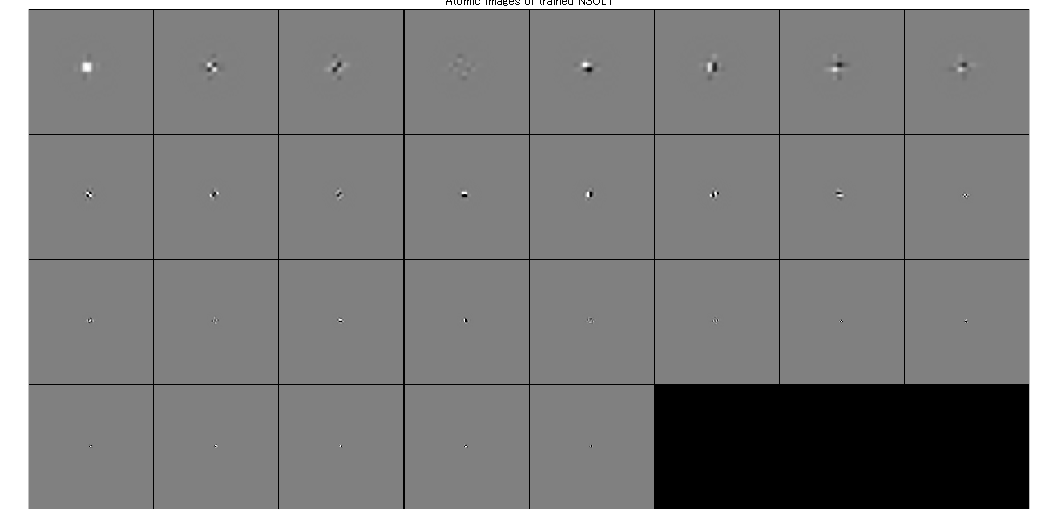

        % Synthesis dictionary update
        trainlgraph = synthesislgraph.replaceLayer('Lv1_Out',...
            regressionLayer('Name','Lv1_Out'));
        trainednet = trainNetwork(coefimgds,trainlgraph,opts);

        % Analysis dictionary update (Copy parameters from synthesizer to analyzer)
        trainedlgraph = layerGraph(trainednet);

        analysislgraph = fcn_cpparamssyn2ana(analysislgraph,trainedlgraph);
        analysisnet = dlnetwork(analysislgraph);

        % Check the adjoint relation (perfect reconstruction)
        checkadjointrelation(analysislgraph,trainedlgraph,nLevels,szPatchTrn);

        % Replace layer
        synthesislgraph = trainedlgraph.replaceLayer('Lv1_Out',...
            nsoltIdentityLayer('Name','Lv1_Out'));
        synthesisnet = dlnetwork(synthesislgraph);

    end
    %profile off
    %profile viewer

### 訓練ネットワークの保存

(Save the designed network)

    import saivdr.dcnn.*
    synthesislgraph = layerGraph(synthesisnet);
    analysislgraph = fcn_cpparamssyn2ana(analysislgraph,synthesislgraph);
    analysisnet = dlnetwork(analysislgraph);
    save(sprintf('./data/nsoltdictionary_%s',datetime('now','Format','yyyyMMddHHmmssSSS')),'analysisnet','synthesisnet','nLevels')
end

### 訓練辞書の要素画像

(The atomic images of trained dictionary)

analysislgraph = layerGraph(analysisnet);
synthesislgraph = layerGraph(synthesisnet);

figure
subplot(1,2,1)
plot(analysislgraph)
title('Analysis NSOLT')
subplot(1,2,2)
plot(synthesislgraph)
title('Synthesis NSOLT')

import saivdr.dcnn.*

figure

atomicimshow(synthesisnet,[],2^(nLevels-1))
title('Atomic images of trained NSOLT')

### 繰返しハード閾値処理関数

(Function of iterative hard thresholding)

The input images of the patch pairs are replaced with sparse coefficients obtained by IHT, where normalization is omitted for the Parseval tight property of NSOLT ( $\mathbf{DD}^T=\mathbf{I}$ ).

         
$$\mathbf{s}^{(t+1)}\leftarrow \mathcal{H}_{T_K}\left(\mathbf{s}^{(t)}-\gamma \hat{\mathbf{D}}^T\left(\hat{\mathbf{D}}\mathbf{s}^{(t)}-\mathbf{v}\right)\right)$$


        
$$t\leftarrow t+1$$


where

        
$$[\mathcal{H}_{T_K}(\mathbf{x})]_i=\left\{\begin{array}{ll} 0 , & |[\mathbf{x}]_i| \leq T_K \\ [\mathbf{x}]_i, & |[\mathbf{x}]_i|> T_K \end{array}\right.$$


【Reference】

-  T. Blumensath and M. E. Davies, "Normalized Iterative Hard Thresholding: Guaranteed Stability and Performance," in IEEE Journal of Selected Topics in Signal Processing, vol. 4, no. 2, pp. 298-309, April 2010, doi: 10.1109/JSTSP.2010.2042411.

#### 深層学習配列に対する繰返しハード閾値処理(IHT)のバッチ処理

(Iterative Hard Thresholding (IHT) batch processing for deep learning arrays)

function newdata = iht4patchds(oldtbl,analyzer,synthesizer,sparsityRatio)
% IHT for InputImage in randomPatchExtractionDatastore
%
nInputs = length(synthesizer.InputNames);

% Apply IHT process for every input patch
restbl = removevars(oldtbl,'InputImage');
dlv = dlarray(cat(4,oldtbl.InputImage{:}),'SSCB');
[~,dlcoefs{1:nInputs}] = iht4dlarray(dlv,analyzer,synthesizer,sparsityRatio);
coefs = cellfun(@(x) permute(num2cell(extractdata(x),1:3),[4 1 2 3]),dlcoefs,'UniformOutput',false);
%
nImgs = length(oldtbl.InputImage);
coefarray = cell(nImgs,nInputs);
for iImg = 1:nImgs
    for iInput = 1:nInputs
        coefarray{iImg,iInput} = coefs{iInput}{iImg};
    end
end
% Output as a cell in order to make multiple-input datastore
newdata = [ coefarray table2cell(restbl) ];
end

#### 深層学習配列に対する繰返しハード閾値処理(IHT)

(Iterative hard thresholding (IHT) for deep learning arrays)

function [dly,varargout] = iht4dlarray(dlx,analyzer,synthesizer,sparsityRatio)
% IHT Iterative hard thresholding
%
nInputs = length(synthesizer.InputNames);
szBatch = size(dlx,4);

% Iterative hard thresholding w/o normalization
% (A Parseval tight frame is assumed)
gamma = (1.-1e-3);
nIters = 10;
nCoefs = floor(sparsityRatio*numel(dlx(:,:,:,1)));
[dlcoefs{1:nInputs}] = analyzer.predict(dlarray(zeros(size(dlx),'like',dlx),'SSCB'));
% IHT
for iter=1:nIters
    % Gradient descent
    dly = synthesizer.predict(dlcoefs{1:nInputs});
    [grad{1:nInputs}] = analyzer.predict(dlx-dly);
    dlcoefs = cellfun(@(x,y) x+gamma*y,dlcoefs,grad,'UniformOutput',false);
    % Hard thresholding
    coefvecs = cellfun(@(x) extractdata(reshape(x,[],szBatch)),dlcoefs,'UniformOutput',false);
    srtdabscoefs = sort(abs(cell2mat(coefvecs.')),1,'descend');
    thk = reshape(srtdabscoefs(nCoefs,:),1,1,1,szBatch);
    dlcoefs = cellfun(@(x) (abs(x)>thk).*x,dlcoefs,'UniformOutput',false);
    % Monitoring
    %checkSparsity =...
    %nnz(srtdabscoefs>srtdabscoefs(nCoefs,:))/numel(dlx)<=sparsityRatio;
    %assert(checkSparsity)
    %fprintf("IHT(%d) MSE: %6.4f\n",iter,mse(dlx,dly));
end
varargout = dlcoefs;
end

#### NSOLTネットワークの随伴関係の確認

(Confirmation of NSOLT network adjoint relations)

function checkadjointrelation(analysislgraph,synthesislgraph,nLevels,szInput)
import saivdr.dcnn.*
x = rand(szInput,'single');
% Assemble analyzer
analysislgraph4predict = analysislgraph;
for iLayer = 1:length(analysislgraph4predict.Layers)
    layer = analysislgraph4predict.Layers(iLayer);
    if contains(layer.Name,"Lv"+nLevels+"_DcOut") || ...
            ~isempty(regexp(layer.Name,'^Lv\d+_AcOut','once'))
        analysislgraph4predict = analysislgraph4predict.replaceLayer(layer.Name,...
            regressionLayer('Name',layer.Name));
    end
end
analysisnet4predict = assembleNetwork(analysislgraph4predict);

% Assemble synthesizer
synthesislgraph4predict = synthesislgraph;
synthesisnet4predict = assembleNetwork(synthesislgraph4predict);

% Analysis and synthesis process
[s{1:nLevels+1}] = analysisnet4predict.predict(x);
if isvector(s{end-1})
    s{end-1} = permute(s{end-1},[1,3,2]);
end
y = synthesisnet4predict.predict(s{:});

% Evaluation
display("MSE: " + num2str(mse(x,y)))
end

© Copyright, Shogo MURAMATSU, All rights reserved.